# **Escuela Politécnica Nacional**

# **Redes Neuronales**

# **Tarea 6: Dataset Carsmall**

**Realizado por: **David Fabián Cevallos Salas

**Fecha: **2023-08-15

En este apartado analizaremos mediante diferentes algoritmos el Dataset carsmall, el cual comprende un problema de regresión.

**DT = **Decision Tree

**RF = **Random Forest

**DNN**= Deep Neuronal Network

**LDA = **Linear Discriminant Analysis

**ANFIS =  **Adaptive Neuro Fuzzy Inference System

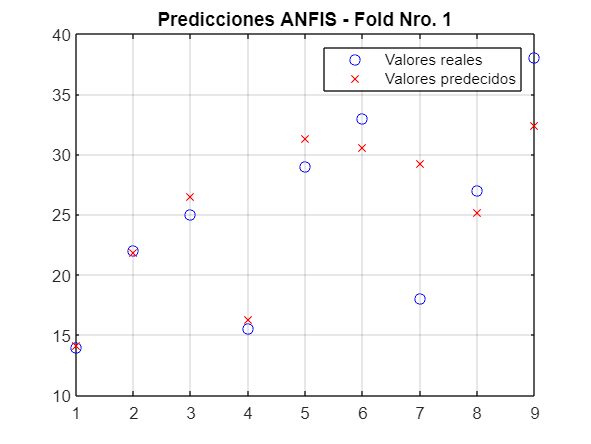

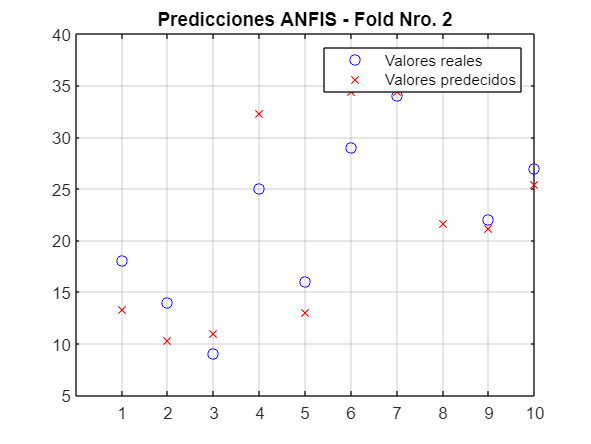

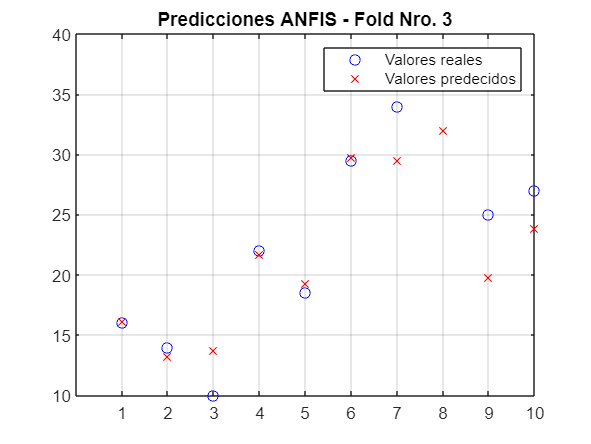

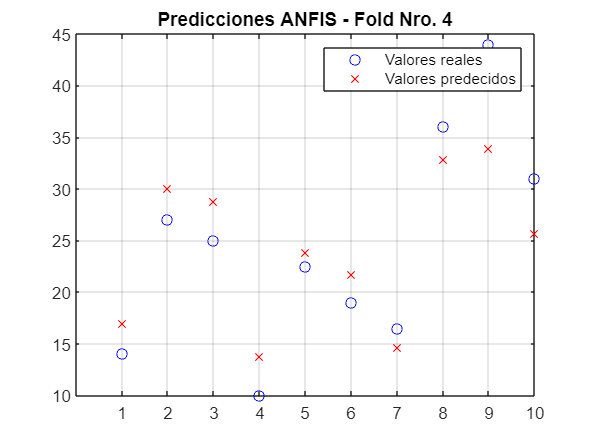

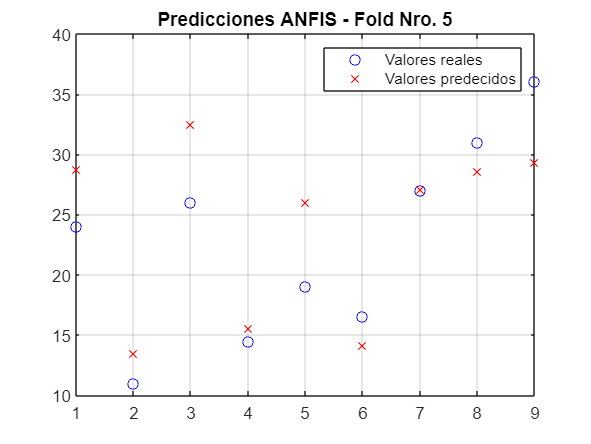

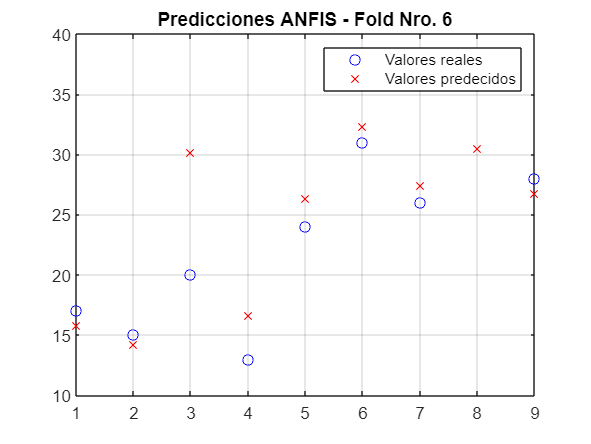

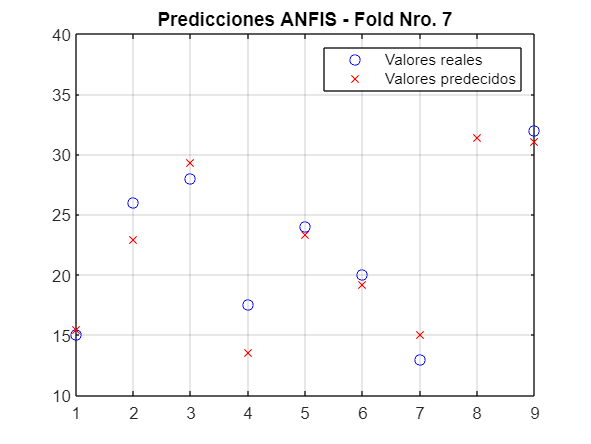

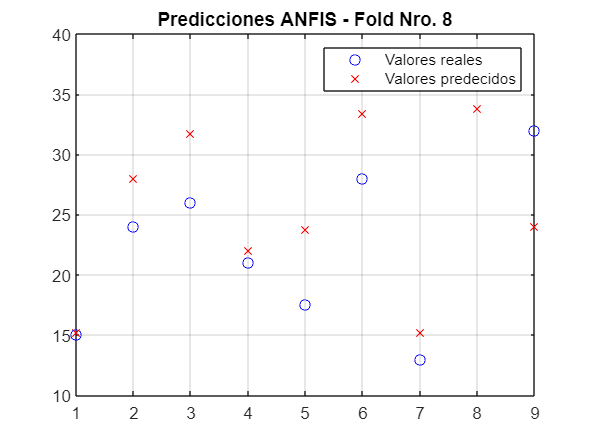

% Dataset Carsmall
tic
clc;
clear;
rng(0);
warning("off","all");

% Carga y limpieza de datos
load carsmall;

Datos = [Weight, Cylinders, Horsepower, MPG];

% Si se desea usar todos los campos, descomentar esta línea
% Observación: El modelo no mejora después de incorporar el 
% resto de campos

%Datos = table(Acceleration, Cylinders, Displacement, Horsepower, ...
    %double(categorical(string(Mfg))), ...
    %double(categorical(string(Model))), ... 
    %Model_Year, ...
    %double(categorical(string(Origin))), ...
    %Weight, MPG);

Datos = rmmissing(Datos);

X = Datos(:, 1:3);
Y = Datos(:, 4);

% Método 10-folding 
CVO = cvpartition(Y,"k",10);
num_pruebas = CVO.NumTestSets;

for i = 1:num_pruebas
    trIdx = CVO.training(i);
    teIdx = CVO.test(i);
    
    % Decision Tree
    ctree = fitrtree(X(trIdx,:), Y(trIdx,:), "MinLeafSize", 30);
    Ypred_dt = predict(ctree, X(teIdx,:));
    Met_dt(1,i) = mse(Y(teIdx,:), Ypred_dt);
    Met_dt(2,i) = power(corr2(Y(teIdx,:), Ypred_dt),2);

    % Random Forest
    rf = TreeBagger(200, X(trIdx,:), Y(trIdx,:), "Method", "regression", "OOBPrediction", "On", "MinLeafSize", 30);
    Ypred_rf = predict(rf, X(teIdx,:));
    Met_rf(1,i) = mse(Y(teIdx,:), Ypred_rf);
    Met_rf(2,i) = power(corr2(Y(teIdx,:), Ypred_rf),2);

    % Deep Neuronal Network
    dnn = fitrnet(X(trIdx,:), Y(trIdx,:), ...
          "LayerSizes", [32 32], ...
          "Activations","relu", ...
          "Lambda", 0.004, ...
          "IterationLimit", 1000, ...
          "Standardize", true);
     Ypred_dnn = predict(dnn, X(teIdx,:));
     Met_dnn(1,i) = mse(Y(teIdx,:), Ypred_dnn);
     Met_dnn(2,i) = power(corr2(Y(teIdx,:), Ypred_dnn),2);
    
    % ANFIS
    opt = anfisOptions;
    opt.InitialFIS = 3;
    opt.EpochNumber = 100;
    opt.OptimizationMethod = 0;
    opt.DisplayANFISInformation = 0;
    opt.DisplayErrorValues = 0;
    opt.DisplayStepSize = 0;
    opt.DisplayFinalResults = 0;
     
    anfis_model = anfis([X(trIdx,:) Y(trIdx,:)], opt);
    Ypred_anfis = evalfis(anfis_model, X(teIdx,:));
    Met_anfis(1,i) = mse(Y(teIdx,:), Ypred_anfis);
    Met_anfis(2,i) = power(corr2(Y(teIdx,:), Ypred_anfis),2);

    % Gráfica de predicciones ANFIS
    figure;
    plot(Y(teIdx,:),"ob");
    hold on
    plot(Ypred_anfis,"xr")
    grid on;
    title(strcat("Predicciones ANFIS - Fold Nro. ", string(i)));
    legend("Valores reales","Valores predecidos");
    ax = gca;
    ax.XTick = unique(round(ax.XTick));
    hold off;
end


% Obtención de métricas finales
Metricas_dt = mean(Met_dt,2)

Metricas_dt =    28.3278
    0.5917


Metricas_rf = mean(Met_rf,2)

Metricas_rf =    19.7890
    0.7541


Metricas_dnn = mean(Met_dnn,2)

Metricas_dnn =    30.9922
    0.6218


Metricas_anfis = mean(Met_anfis,2)

Metricas_anfis =    18.1389
    0.7628


toc

Elapsed time is 13.648986 seconds.


**Conclusión**

 Se puede concluir, de manera general, que para todos los casos las métricas de menor valor corresponden a las obtenidas a través del árbol de decisión individual (DT).

En lo referente al problema de regresión, las mejores métricas fueron obtenidas con los algoritmos Random Forest (RF) y ANFIS, seguido de la red neuronal profunda (DNN) y finalmente del árbol de decisión individual (DT).